## **Manipulation d’objets sous Matlab**

Juliette BLUEM

08/11/2021


clear
clc
close all

### Remise en forme

Vecteurs

a=[2 4 6 8];
a(1,2)

ans = 4

a(3)

ans = 6

a(1:3)

ans =      2     4     6


Matrices

X=[1 2 3 4;5 6 7 8]

X =      1     2     3     4
     5     6     7     8


### Jeu de mots

Enregistrement d’une courte phrase à l’aide de votre smartphone

[x,fs] = audioread('MaPhrase.mp3');
t = (0:length(x)-1)' * 1/fs;

Visualisation du signal enregistré

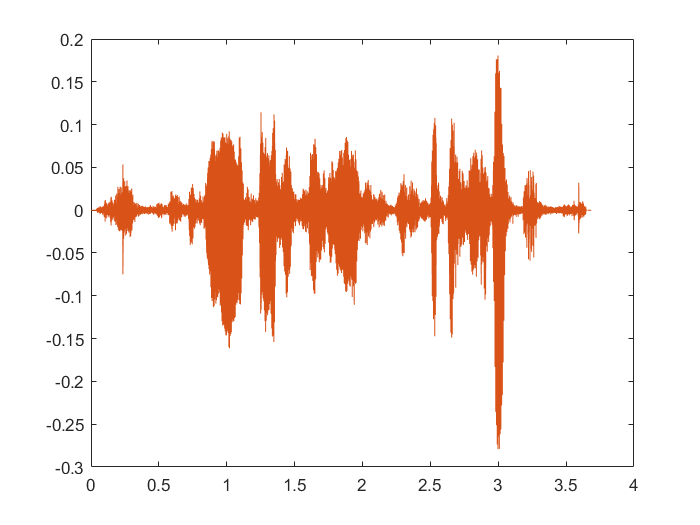

plot(t,x),

shg

Ecoute

%fs=22050; % Change le genre de la voix
%sound(x, fs)

Segmentation

riennesertde = x(38000:73000);
courir = x(73000:100000); 
ilfaut = x(100000:124000);
partirapoint = x(124000:165000);

phrase = [riennesertde partirapoint ilfaut courir];
sound(phrase, fs)

### **Reconstitution d’un signal créneau à partir de sa décomposition en série de Fourier**  

Partie continue 

    nulle

Fondamental 

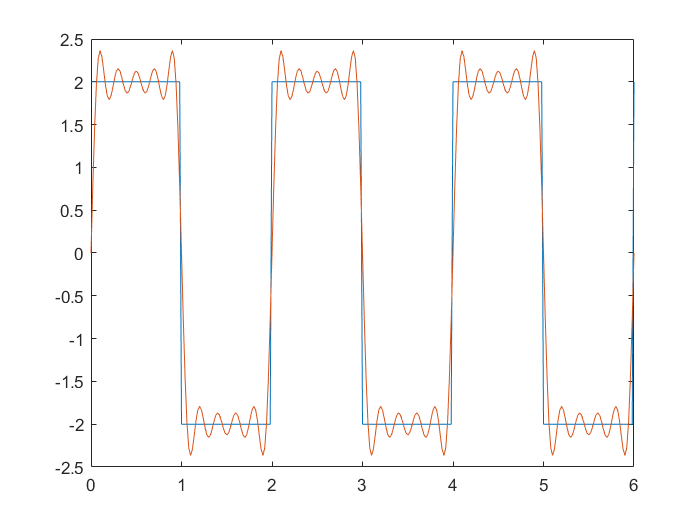


A=2;
To=2 ;
fo=1/To;
fe=100*fo; % Théorème de Shannon fe > 2*fmax
Te=1/fe;
t= 0:Te:(3*To) ;
base=A*square(2*pi*fo*t); % Signal creneau

h1=4*A/pi*sin(2*pi*fo*t);
h3=4*A/(3*pi)*sin(2*pi*3*fo*t);
h5=4*A/(5*pi)*sin(2*pi*5*fo*t);
h7 = 4*A/(7*pi)*sin(2*pi*7*fo*t);
h9 = 4*A/(9*pi)*sin(2*pi*9*fo*t);
test = h1 + h3 + h5 + h7 + h9;
plot(t, base, t, test)